# Machine Learning Online Class

## Initialization

clear ; close all; clc

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


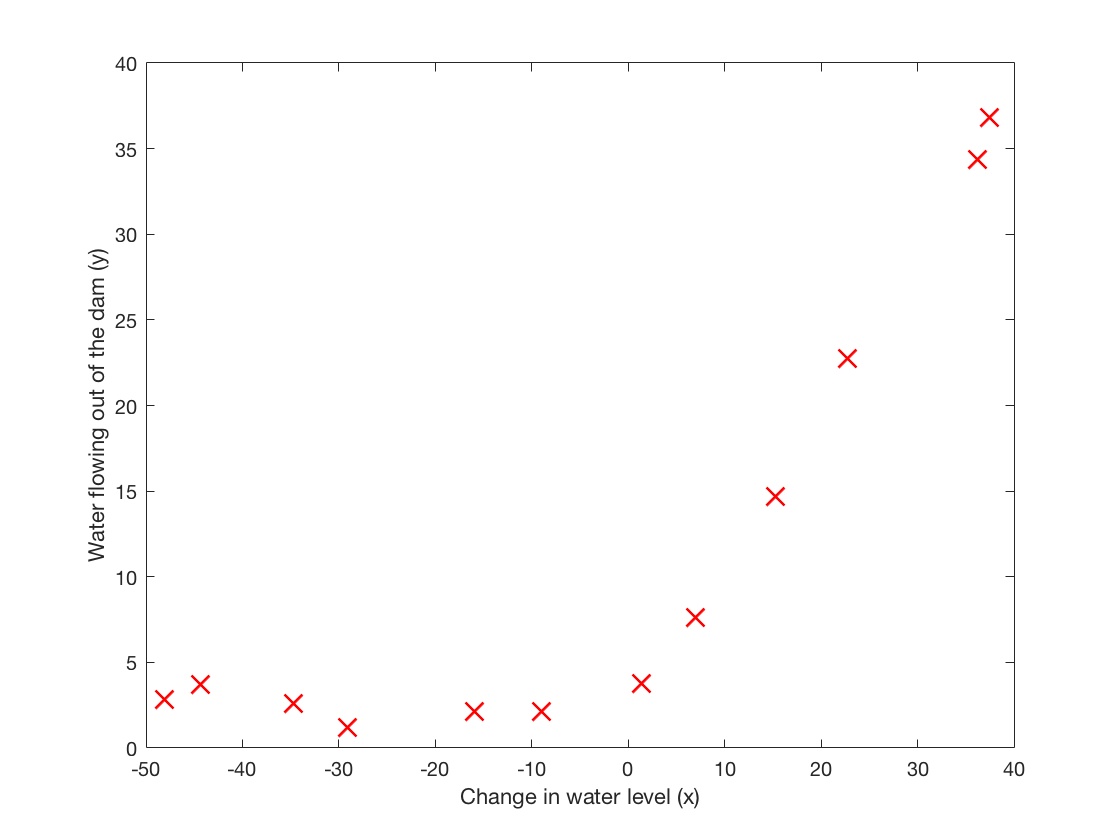


% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');

% m = Number of examples
m = size(X, 1);

% Plot training data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 2: Regularized Linear Regression Cost =============

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Cost at theta = [1 ; 1]: %f '...
         '\n(this value should be about 303.993192)\n'], J);

Cost at theta = [1 ; 1]: 303.993192 
(this value should be about 303.993192)



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 3: Regularized Linear Regression Gradient =============

theta = [1 ; 1];
[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Gradient at theta = [1 ; 1]:  [%f; %f] '...
         '\n(this value should be about [-15.303016; 598.250744])\n'], ...
         grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 
(this value should be about [-15.303016; 598.250744])



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 4: Train Linear Regression =============

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01


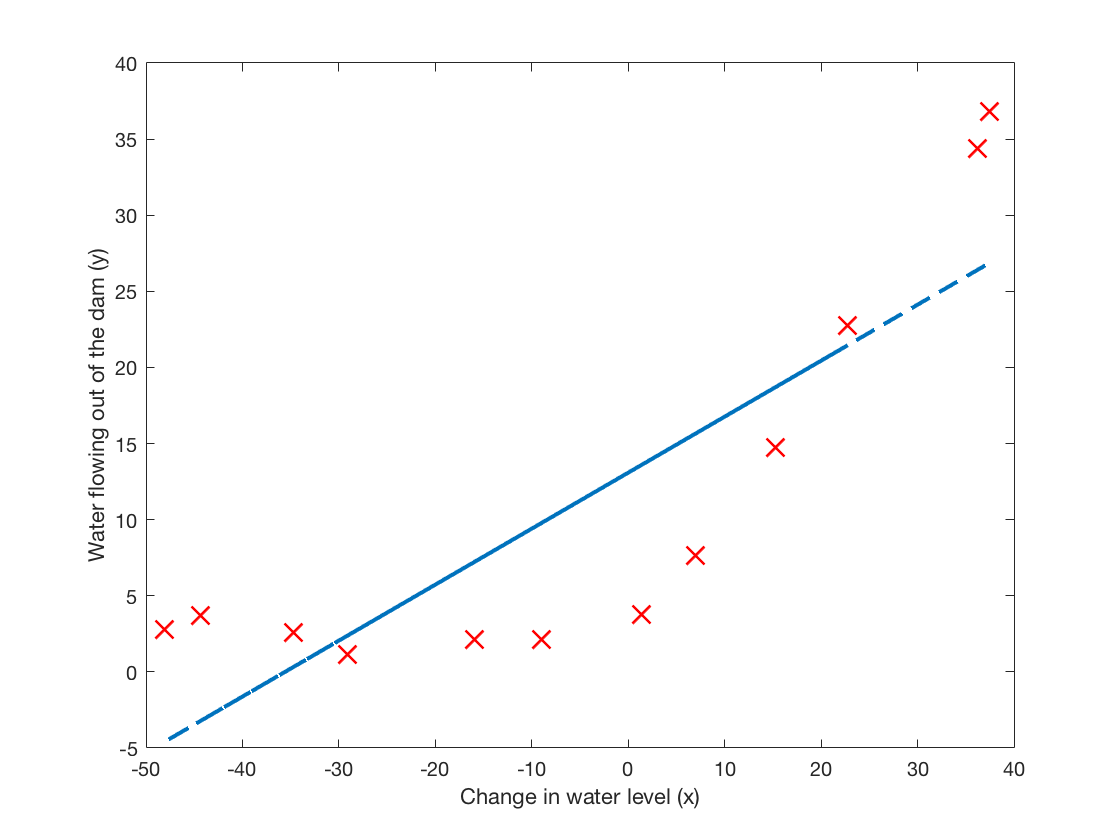


%  Plot fit over the data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)
hold off;


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 5: Learning Curve for Linear Regression =============

lambda = 0;
[error_train, error_val] = ...
    learningCurve([ones(m, 1) X], y, ...
                  [ones(size(Xval, 1), 1) Xval], yval, ...
                  lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     4 | Cost: 3.286595e+00
Iteration     5 | Cost: 3.286595e+00
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.843147e+00
Iteration     7 | Cost: 2.842791e+00
Iteration     8 | Cost: 2.842765e+00
Iteration     9 | Cost: 2.842679e+00
Iteration    10 | Cost: 2.842679e+00
Iteration    11 | Cost: 2.842679e+00
Iteration    12 | Cost: 2.842678e+00
Iteration    13 | Cost: 2.842678e+00
Iteration    14 | Cost: 2.842678e+00
Iteration    15 | Cost: 2.842678e+00
Iteration    16 | Cost: 2.842678e+00
Iteration    17 | Cost: 2.842678e+00
I

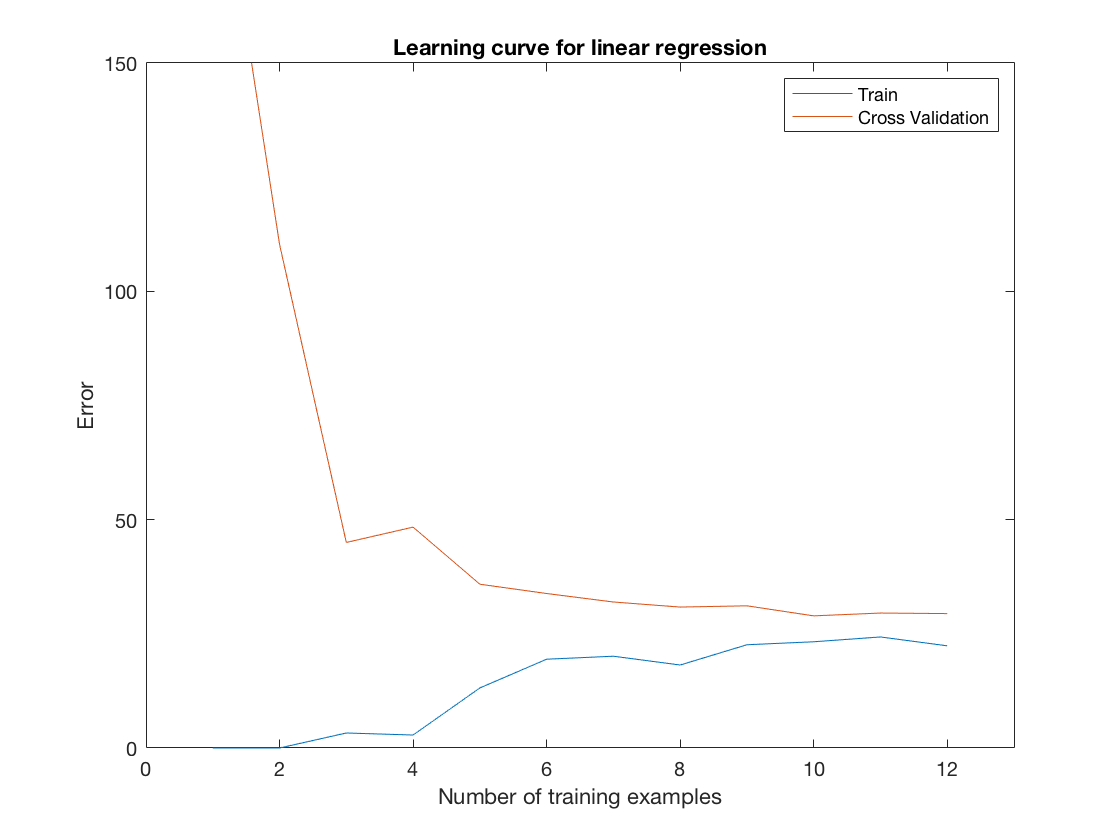


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 6: Feature Mapping for Polynomial Regression =============

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = bsxfun(@minus, X_poly_test, mu);
X_poly_test = bsxfun(@rdivide, X_poly_test, sigma);
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = bsxfun(@minus, X_poly_val, mu);
X_poly_val = bsxfun(@rdivide, X_poly_val, sigma);
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  -0.362141  
  -0.755087  
  0.182226  
  -0.706190  
  0.306618  
  -0.590878  
  0.344516  
  -0.508481  








fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## =========== Part 7: Learning Curve for Polynomial Regression =============

lambda = 1;
[theta] = trainLinearReg(X_poly, y, lambda);

Iteration     1 | Cost: 8.320954e+01
Iteration     2 | Cost: 2.907694e+01
Iteration     3 | Cost: 1.613078e+01
Iteration     4 | Cost: 7.918500e+00
Iteration     5 | Cost: 7.785581e+00
Iteration     6 | Cost: 7.600404e+00
Iteration     7 | Cost: 7.574121e+00
Iteration     8 | Cost: 7.489296e+00
Iteration     9 | Cost: 7.375600e+00
Iteration    10 | Cost: 7.357466e+00
Iteration    11 | Cost: 7.346349e+00
Iteration    12 | Cost: 7.308684e+00
Iteration    13 | Cost: 7.289264e+00
Iteration    14 | Cost: 7.269127e+00
Iteration    15 | Cost: 7.268747e+00
Iteration    16 | Cost: 7.268312e+00
Iteration    17 | Cost: 7.268290e+00
Iteration    18 | Cost: 7.268207e+00
Iteration    19 | Cost: 7.268197e+00
Iteration    20 | Cost: 7.268192e+00
Iteration    21 | Cost: 7.268189e+00
Iteration    22 | Cost: 7.268178e+00
Iteration    23 | Cost: 7.268166e+00
Iteration    24 | Cost: 7.268165e+00
Iteration    25 | Cost: 7.268159e+00
Iteration    26 | Cost: 7.268153e+00
Iteration    27 | Cost: 7.268150e+00
I

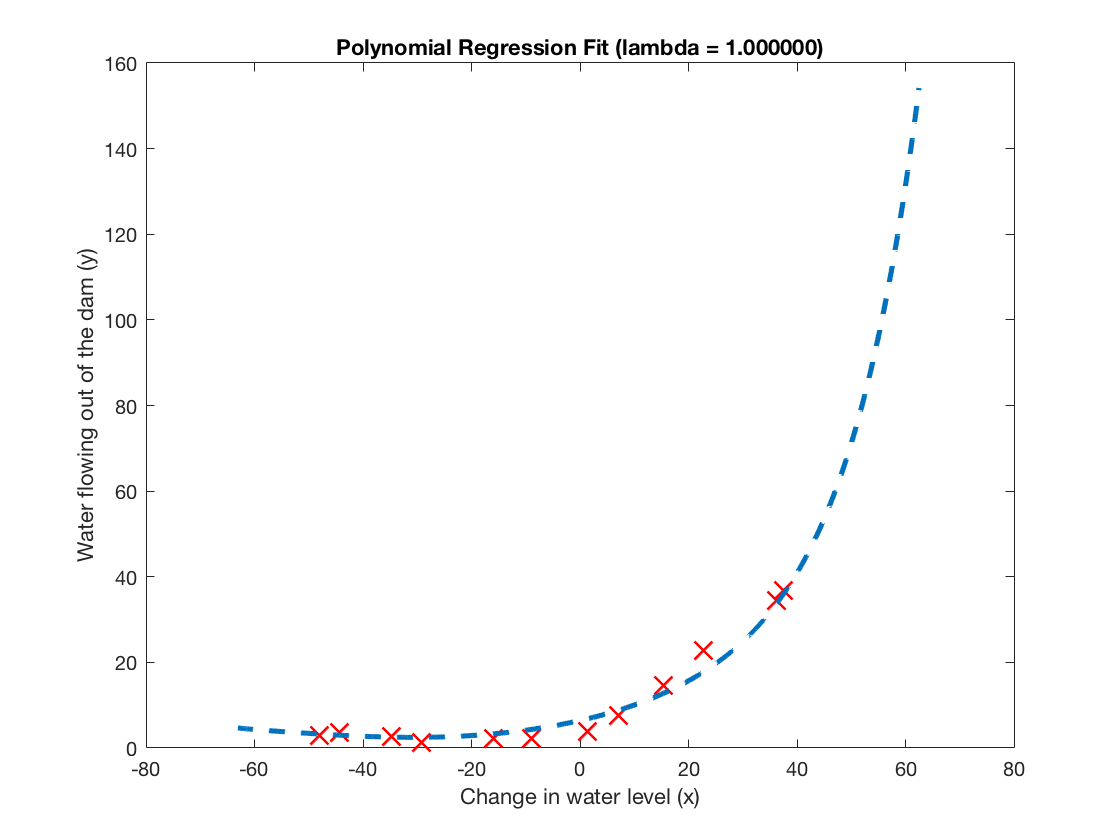


% Plot training data and fit
figure(1);
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));


figure(2);
[error_train, error_val] = ...
    learningCurve(X_poly, y, X_poly_val, yval, lambda);

Iteration     1 | Cost: 5.280051e-01
Iteration     2 | Cost: 2.083531e-01
Iteration     3 | Cost: 9.810873e-02
Iteration     4 | Cost: 1.501116e-03
Iteration     5 | Cost: 1.089480e-03
Iteration     6 | Cost: 5.204709e-31
Iteration     7 | Cost: 1.745286e-31
Iteration     8 | Cost: 3.643730e-32
Iteration     9 | Cost: 6.001848e-33
Iteration    10 | Cost: 9.121147e-34
Iteration    11 | Cost: 1.855909e-62
Iteration    12 | Cost: 2.113260e-65
Iteration    13 | Cost: 6.814360e-71
Iteration    14 | Cost: 2.197339e-76
Iteration    15 | Cost: 7.085478e-82
Iteration    16 | Cost: 2.284763e-87
Iteration    17 | Cost: 7.367384e-93
Iteration    18 | Cost: 2.375666e-98
Iteration    19 | Cost: 7.660505e-104
Iteration    20 | Cost: 2.470185e-109
Iteration    21 | Cost: 7.965288e-115
Iteration    22 | Cost: 2.568464e-120
Iteration    23 | Cost: 8.282198e-126
Iteration    24 | Cost: 2.670654e-131
Iteration    25 | Cost: 8.611716e-137
Iteration    26 | Cost: 2.776910e-142
Iteration    27 | Cost: 8.9543

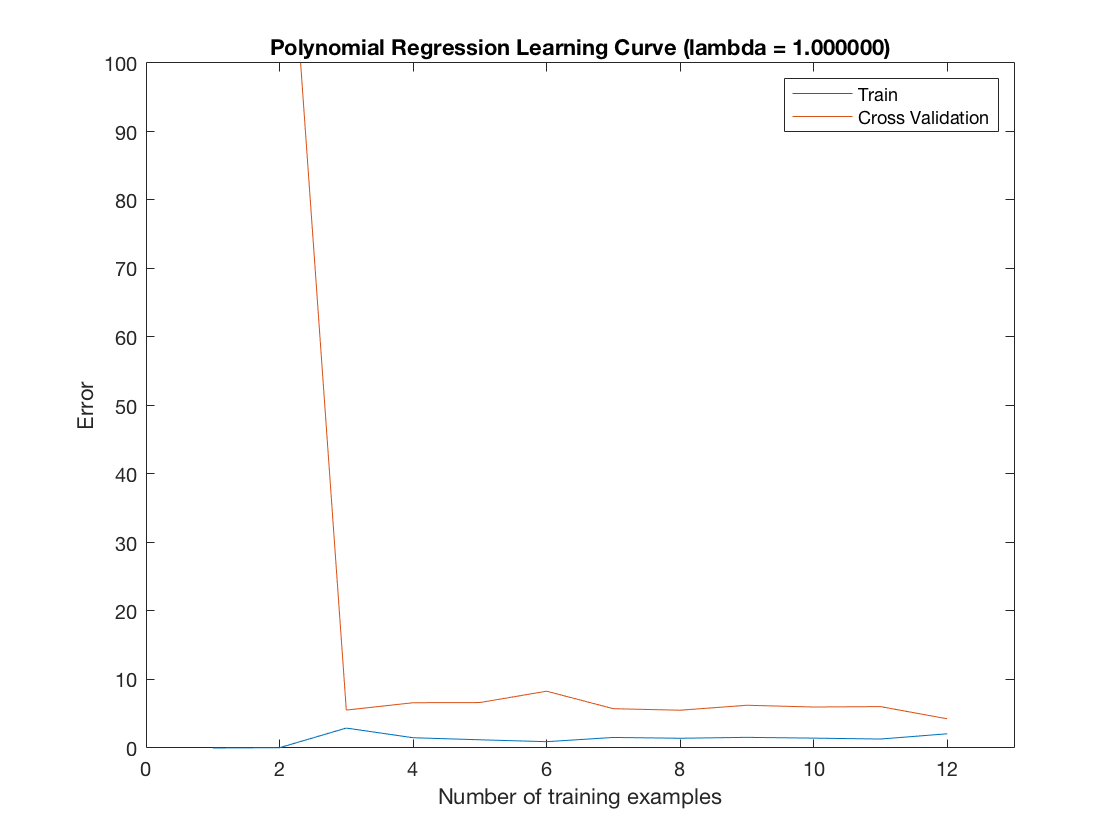

plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')


fprintf('Polynomial Regression (lambda = %f)\n\n', lambda);

Polynomial Regression (lambda = 1.000000)



fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	138.846777
  	2		0.045772	143.522890
  	3		2.911375	5.534713
  	4		1.499413	6.609883
  	5		1.199183	6.634076
  	6		0.924511	8.291979
  	7		1.540897	5.737166
  	8		1.422968	5.516444
  	9		1.553733	6.239740
  	10		1.441565	5.983046
  	11		1.308147	6.043752
  	12		2.076188	4.260626



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 8: Validation for Selecting Lambda =============

[lambda_vec, error_train, error_val,error_test] = ...
    validationCurve(X_poly, y, X_poly_val, yval,X_poly_test,ytest);

Iteration     1 | Cost: 8.273077e+01
Iteration     2 | Cost: 2.687496e+01
Iteration     3 | Cost: 1.327780e+01
Iteration     4 | Cost: 3.455324e+00
Iteration     5 | Cost: 2.870493e+00
Iteration     6 | Cost: 2.404364e+00
Iteration     7 | Cost: 2.372779e+00
Iteration     8 | Cost: 1.771555e+00
Iteration     9 | Cost: 1.210317e+00
Iteration    10 | Cost: 9.411242e-01
Iteration    11 | Cost: 7.810132e-01
Iteration    12 | Cost: 7.283453e-01
Iteration    13 | Cost: 6.591863e-01
Iteration    14 | Cost: 5.114677e-01
Iteration    15 | Cost: 4.755619e-01
Iteration    16 | Cost: 4.245518e-01
Iteration    17 | Cost: 4.227541e-01
Iteration    18 | Cost: 4.191485e-01
Iteration    19 | Cost: 4.159414e-01
Iteration    20 | Cost: 4.116283e-01
Iteration    21 | Cost: 4.066049e-01
Iteration    22 | Cost: 4.018144e-01
Iteration    23 | Cost: 3.996397e-01
Iteration    24 | Cost: 3.978959e-01
Iteration    25 | Cost: 3.950938e-01
Iteration    26 | Cost: 3.811060e-01
Iteration    27 | Cost: 3.768511e-01
I

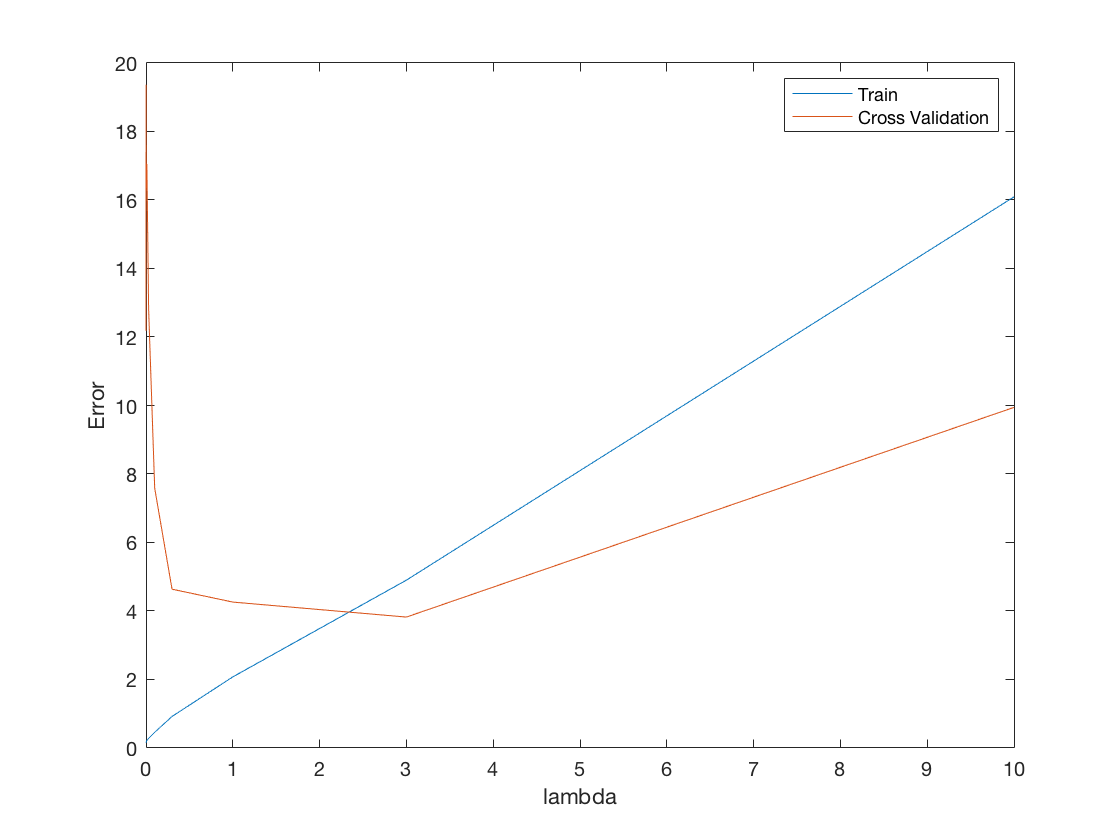


close all;
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');


fprintf('lambda\t\tTrain Error\tValidation Error\n');

lambda		Train Error	Validation Error


for i = 1:length(lambda_vec)
	fprintf(' %f\t%f\t%f\t%f\n', ...
            lambda_vec(i), error_train(i), error_val(i),error_test(i));
end

 0.000000	0.148993	12.177956	18.240766
 0.001000	0.170365	19.363959	19.321288
 0.003000	0.171480	16.334268	16.953550
 0.010000	0.221933	17.053504	15.982249
 0.030000	0.281853	12.829257	13.023114
 0.100000	0.459318	7.587013	9.162913
 0.300000	0.921760	4.636833	5.025049
 1.000000	2.076188	4.260626	2.725985
 3.000000	4.901351	3.822907	3.859888
 10.000000	16.092213	9.945509	17.005349



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;